clear all;
clc;
ts = 0.01;
t = -1000:1000;
M = 10;
y = zeros(1,2001);

%set sn
s = 10*sin(2*pi*ts*t).*(t>=0)+0.*(t<1000);

%set dn
for i = 1:2001
    d = 2*rand(1,i) - 1;
end

%set xn
for i = 1:2001
    x(1,i) = s(1,i) + d(1,i);
end

%set yn
y = zeros(1,2001);
for i = M+1:2001
    temp = 0;
    for n = 1:M
        temp = temp + x(1,i-n);
    end
    y(1,i) = temp / M;
end

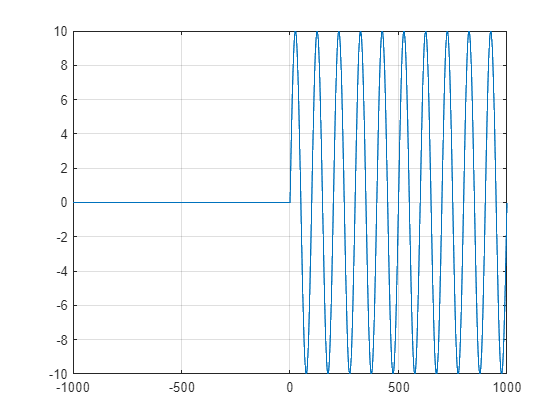

plot(t,s);grid on;

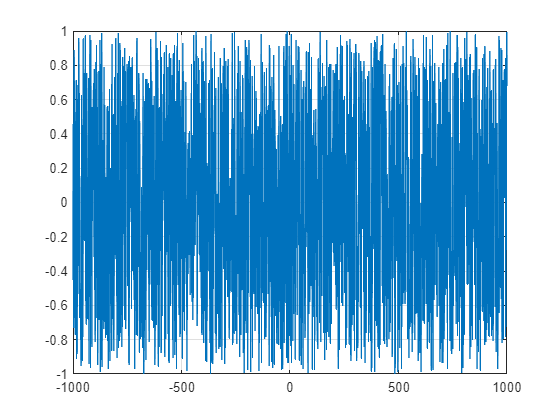

plot(t,d);grid on;

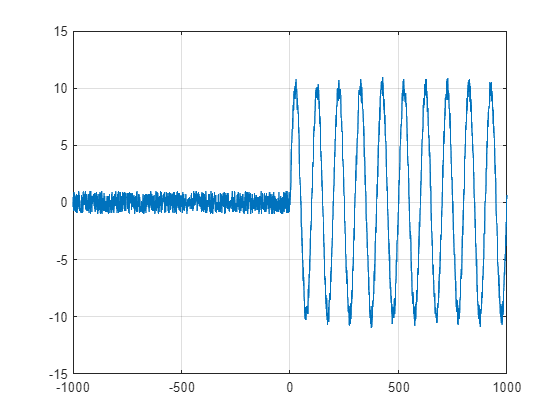

plot(t,x);grid on;

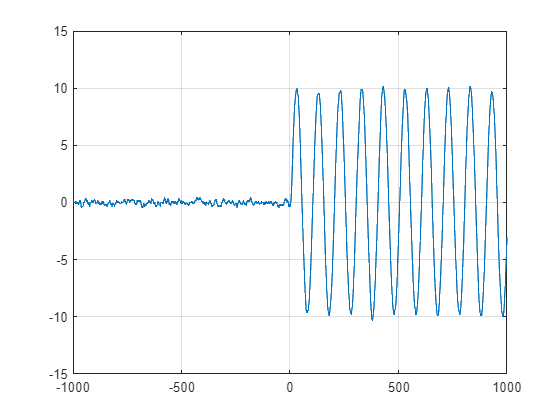

plot(t,y);grid on;